**Ionic Current Model of Bipolar Cells**

Set constants

tspan = [0, 5];

Compute voltage

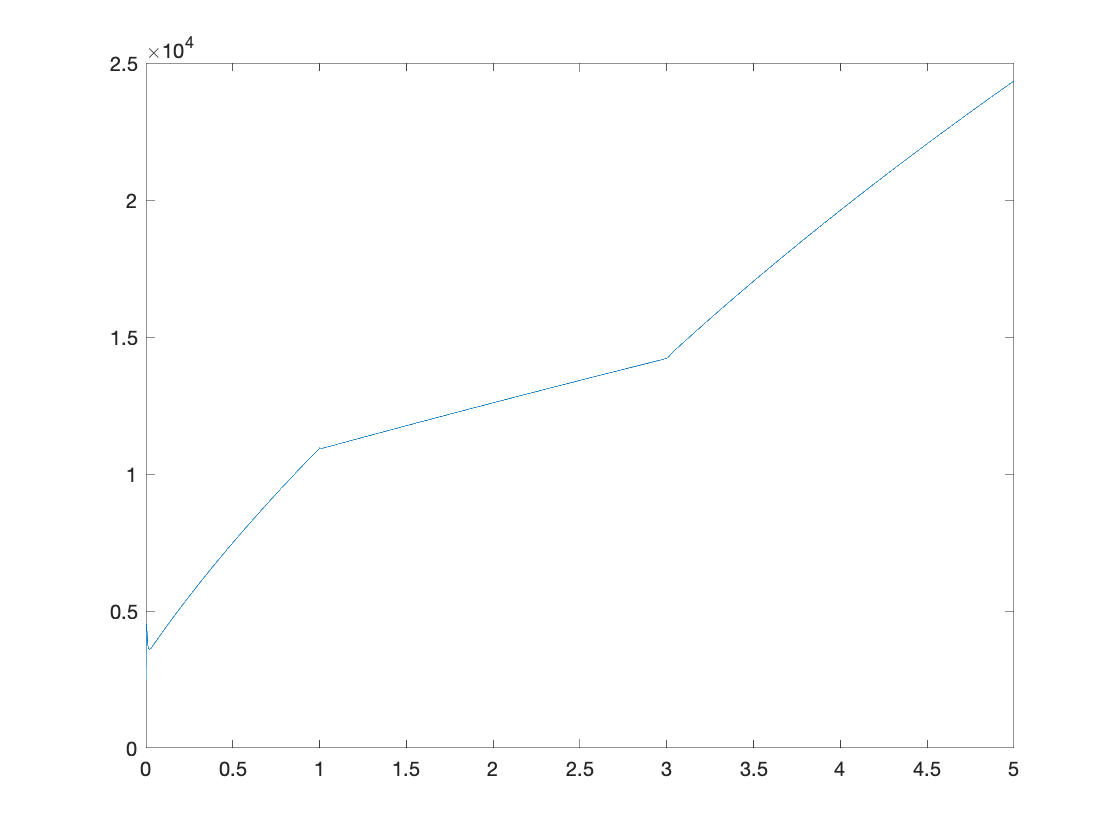

[tV, res] = calcV(tspan);
Cas = res(:,11);
plot(tV, Cas)


V = res(:,5);
plot(tV, V)

title('Voltage')
xlabel('Time')
ylabel('Voltage')

*Calcium current*

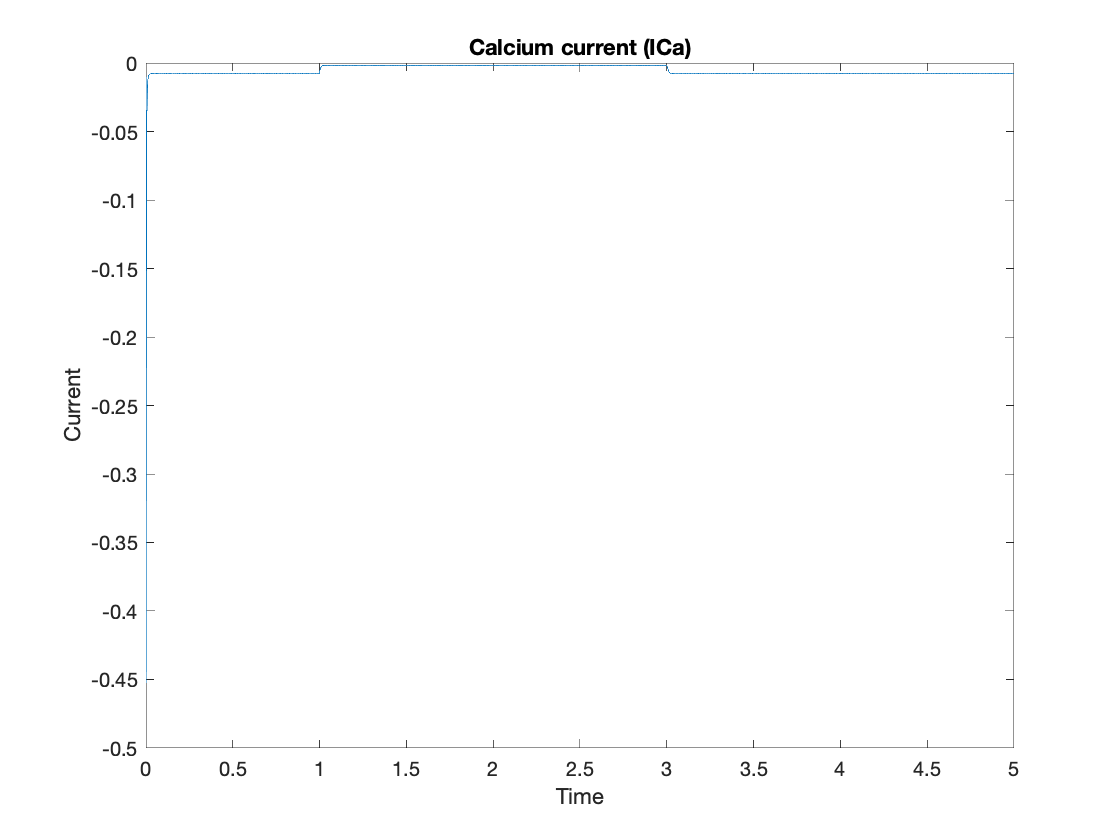

[t, ICa] = calcICa(tspan, tV, V, Cas);
plot(t, ICa)

title('Calcium current (ICa)')
xlabel('Time')
ylabel('Current')

*Calcium-dependent K current*

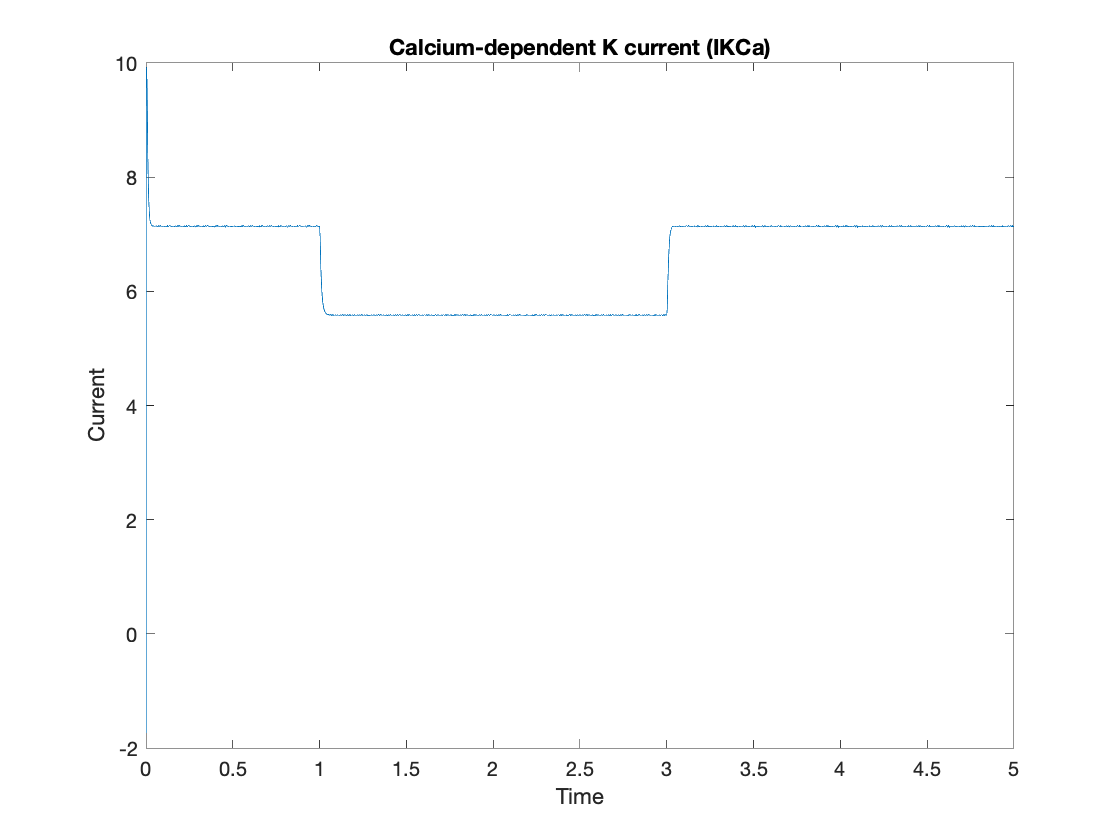

[t, IKCa] = calcIKCa(tspan, tV, V, Cas);
plot(t, IKCa)

% title('Calcium-dependent K current (IKCa)')
xlabel('Time')
ylabel('Current')

*Delayed rectifying potassium current*

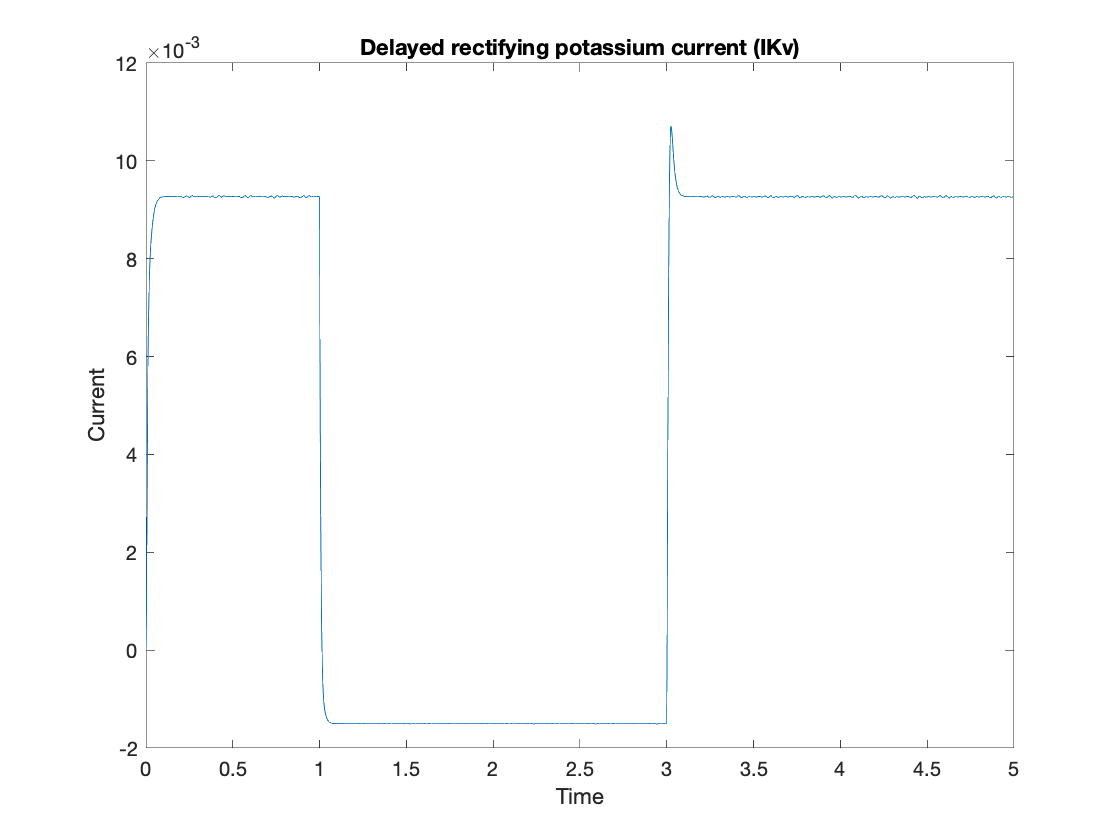

[t, IKv] = calcIKv(tspan, tV, V);
plot(t, IKv)

title('Delayed rectifying potassium current (IKv)')
xlabel('Time')
ylabel('Current')

*Hyperpolarization activated current*

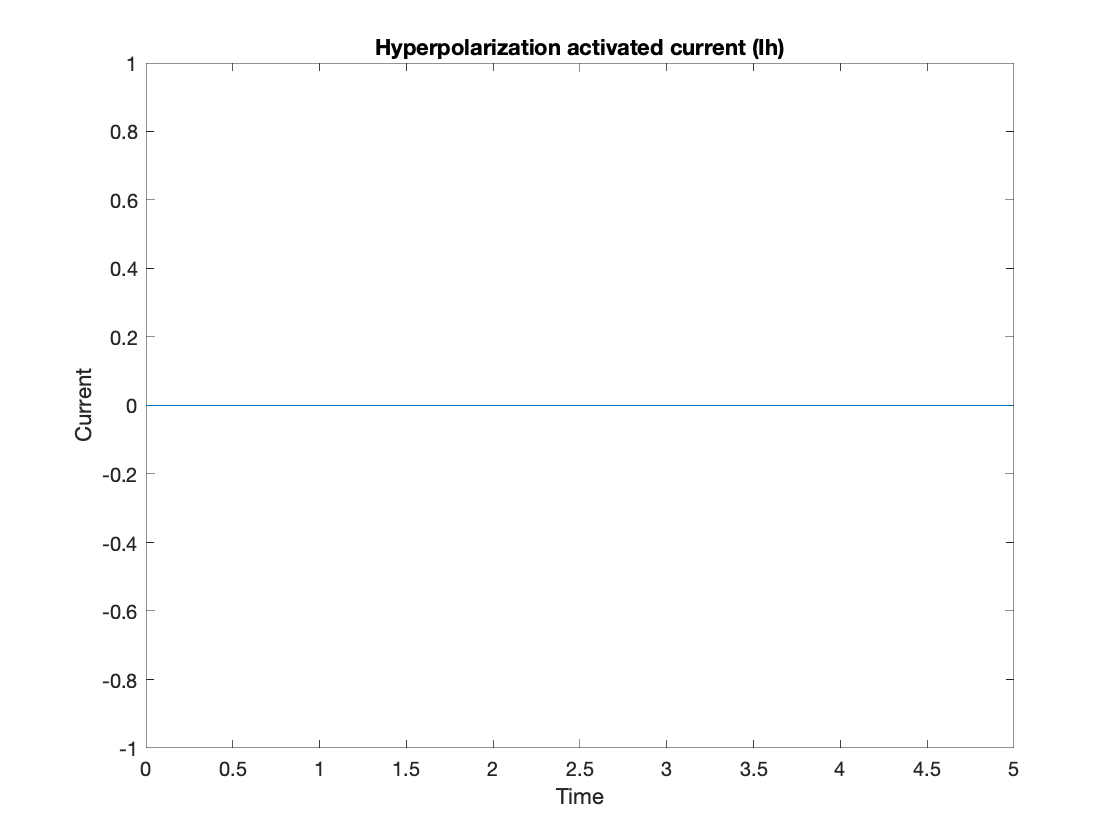

[t, Ih] = calcIh(tspan, tV, V);
plot(t, Ih)

title('Hyperpolarization activated current (Ih)')
xlabel('Time')
ylabel('Current')

*Leakage current*

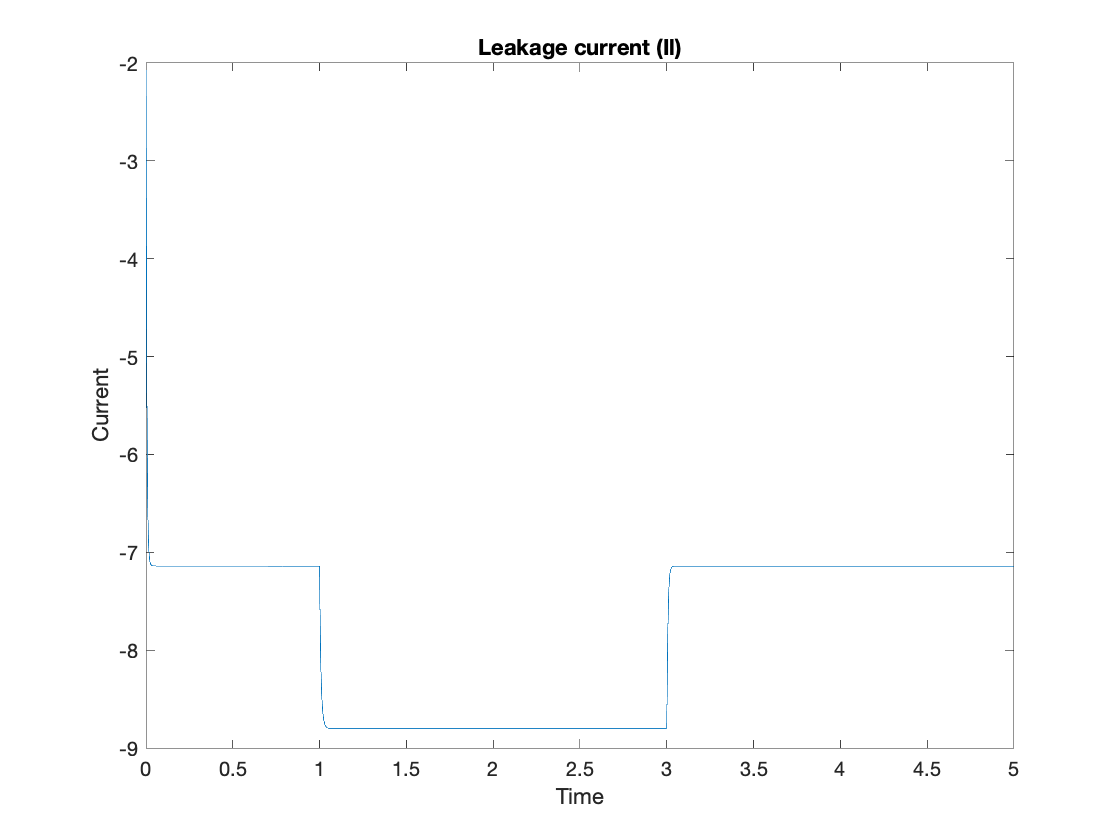

Il = calcIl(V);
plot(tV, Il)

title('Leakage current (Il)')
xlabel('Time')
ylabel('Current')

*Transient outward current (not needed to calculate voltage)*

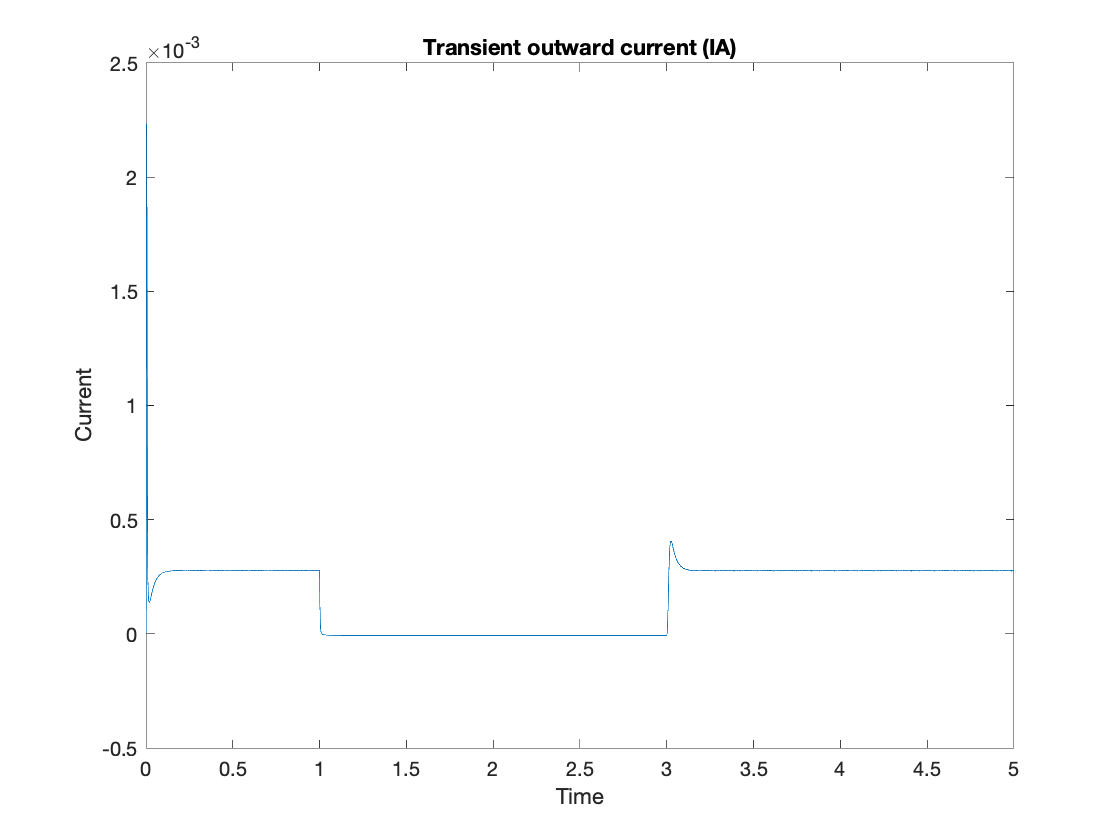

[t, IA] = calcIA(tspan, tV, V);
plot(t, IA)

title('Transient outward current (IA)')
xlabel('Time')
ylabel('Current')